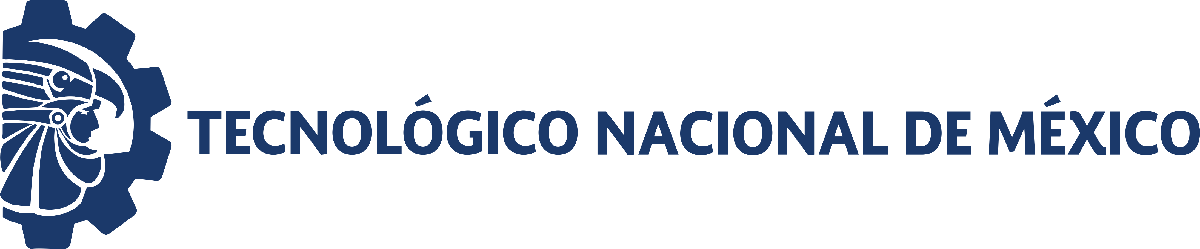                                 [image: logo ITT-2018.png]

# Práctica: Liberación controlada de fármacos por hidrogeles

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Objetivo

Determinar la tasa de liberación del hidrogel N36 2MBA3 con base en los datos experimentales de la siguiente figura.

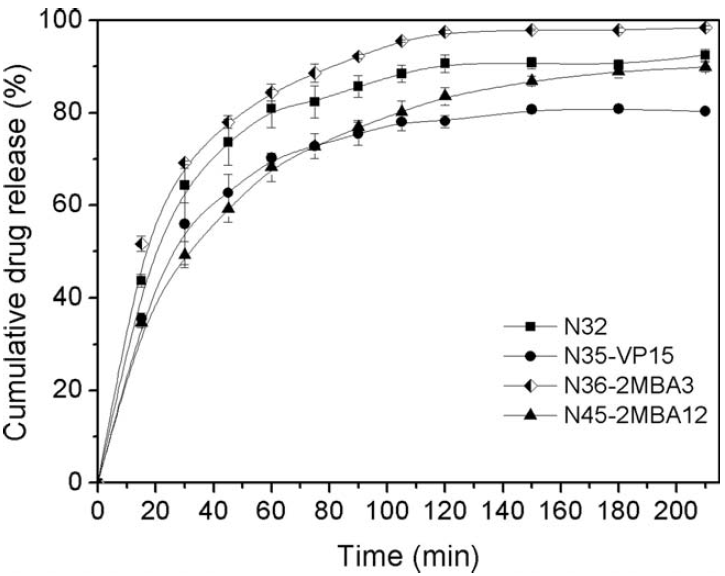

## Referencia

M. A. González‐Ayón, J.A. Sañudo‐Barajas, L.A. Picos‐Corrales, & A. Licea‐Claverie, "PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil", *Journal of Polymer Science Part A: Polymer Chemistry*, vol. 53, issue 22, pp. 2662-2672, Aug 2015. DOI: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

## Modelos a ajustar a los datos experimentales

Ecuación de Peppas: $x\left(t\right)=kt^n$

Farmacocinética de primer orden: $$x(t) = \beta(1 - e^{-kt})$ $

Eureqa: $$X(t) = \rho_1 \cdot \sqrt{t} - \rho_2 \cdot t$$

Eureqa EDO: $    $$\dot{x} = \rho_1 - \rho_2 x$$
$

## Datos experimentales

clc; clear; close all; warning('off','all')
data = 'DATA.csv';
[t,V]=imprimirTabla(data);


--- Datos cargados de: DATA.csv ---
    Tiempo_min    N45_2MBA12    N35_VP15     N32      N36_2MBA3
    __________    __________    ________    ______    _________

         0               0            0          0          0  
        15          34.186       35.488     43.667     51.659  
        30          49.043        55.92     64.099     68.931  
        45          59.066       62.412     73.564     77.653  
        60          68.346       70.019     80.614     84.331  
        75          72.607       72.421     81.901     88.221  
        90          76.682       75.195     85.232     91.738  
       105          79.828       77.783     88.007      95.07  
       120          83.532        77.77     90.223     96.915  
       150          86.478        80.53     90.382     97.444  
       180          88.8

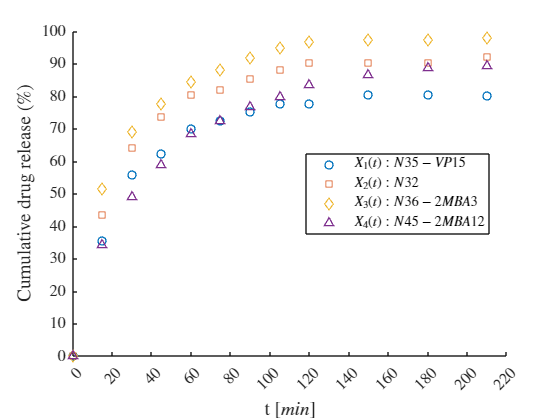

graficarPuntos(data, false, false);

## Regresión no lineal, bioestadísticos y experimentación in silico

labels = ["N45_2MBA12", "N35_VP15", "N32", "N36_2MBA3"];
xp_peppas = zeros(size(V)); 

### Funcion de Pepas

n0 = 0.1; k0 = 0.1; 
for i = 1:4
    disp(['Ajustando Peppas para: ', labels(i)])
    mdl = peppas(t, V(:,i), [k0; n0]);
    xp_peppas(:,i) = mdl.Fitted; 
end

    "Ajustando Peppas para: "    "N45_2MBA12"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE             CI95             Pvalue  
    __________    ________    ________    _______    __________________    __________

      {'k'}         17.62       2.2216       4.95      12.67      22.57    1.2698e-05
      {'n'}       0.31667     0.026856    0.05984    0.25683    0.37651    3.4454e-07

R-cuadrada ordinaria: 0.97881
Suma residual de cuadrados: 166.4173
Criterio de informacion de Akaike ajustado (n/k<40): 70.943

    "Ajustando Peppas para: "    "N35_VP15"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        24.772       3.8281      8.5295     16.242     33.301    7.1534e-05
      {'n'}       0.23512     0.033352    0.074314    0.16081    0.30943    3.5005e-05

R-cuadrada ordinaria: 0.95817
Suma residual de cuadrados: 267.4509
Criterio de informacion de Akaike ajustado (n/k<40): 76.6362

    "Ajustando Peppas para: "    "N32"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        30.499       4.2205      9.4038     21.095     39.903    2.8363e-05
      {'n'}       0.21897     0.029951    0.066734    0.15223     0.2857    2.5684e-05

R-cuadrada ordinaria: 0.96415
Suma residual de cuadrados: 288.2417
Criterio de informacion de Akaike ajustado (n/k<40): 77.5346

    "Ajustando Peppas para: "    "N36_2MBA3"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        34.306        3.791      8.4468     25.859     42.753    3.9394e-06
      {'n'}       0.20911     0.023959    0.053385    0.15572    0.26249    5.4502e-06

R-cuadrada ordinaria: 0.97596
Suma residual de cuadrados: 216.1475
Criterio de informacion de Akaike ajustado (n/k<40): 74.0805

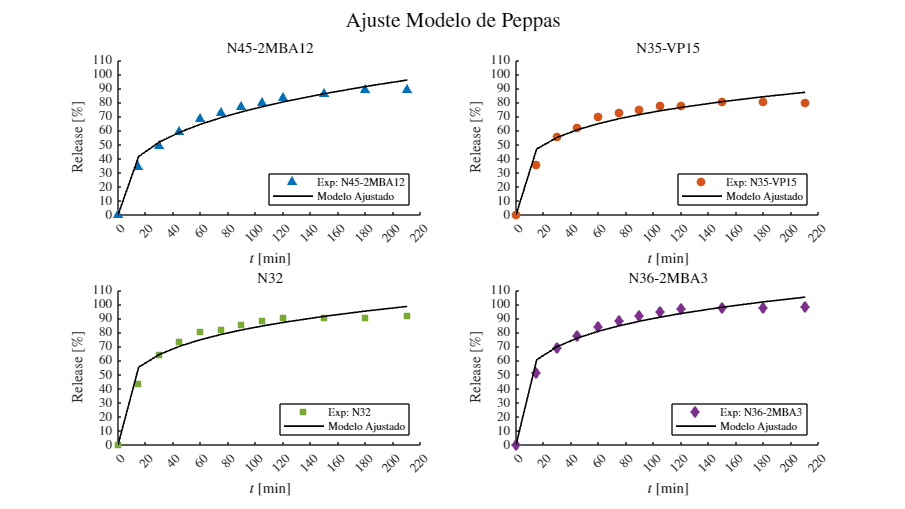

plotResults(t, V, xp_peppas, 'Ajuste Modelo de Peppas', 'Peppas_Result');

### Farmacocinetica $$x(t) = \beta(1 - e^{-kt})$ $

xp_farmaco = zeros(size(V));
k0_f = 0.01; beta0 = 90;
for i = 1:4
    disp(['Ajustando Farmaco para: ', labels(i)])
    mdl = farmaco(t, V(:,i), [k0_f; beta0]);
    xp_farmaco(:,i) = mdl.Fitted; % Guardamos el ajuste
end

    "Ajustando Farmaco para: "    "N45_2MBA12"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE          MoE              CI95              Pvalue  
    __________    ________    _________    _______    ____________________    __________

     {'k'   }     0.026008    0.0014856    0.00331    0.022698    0.029318    7.8519e-09
     {'beta'}        87.53       1.4165     3.1562      84.374      90.687    2.9962e-14

R-cuadrada ordinaria: 0.99158
Suma residual de cuadrados: 66.0922
Criterio de informacion de Akaike ajustado (n/k<40): 59.8616

    "Ajustando Farmaco para: "    "N35_VP15"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'k'   }     0.037492    0.0014692    0.0032735    0.034219    0.040766    1.9589e-10
     {'beta'}       79.217      0.69262       1.5433      77.673       80.76    6.4029e-17

R-cuadrada ordinaria: 0.99614
Suma residual de cuadrados: 24.6916
Criterio de informacion de Akaike ajustado (n/k<40): 48.0465

    "Ajustando Farmaco para: "    "N32"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'k'   }     0.040587    0.0017857    0.0039787    0.036608    0.044566    6.1241e-10
     {'beta'}       89.548      0.83534       1.8613      87.687      91.409     1.223e-16

R-cuadrada ordinaria: 0.99519
Suma residual de cuadrados: 38.7032
Criterio de informacion de Akaike ajustado (n/k<40): 53.4401

    "Ajustando Farmaco para: "    "N36_2MBA3"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE              CI95              Pvalue  
    __________    ________    _________    _________    ___________________    __________

     {'k'   }     0.042271    0.0028956    0.0064517    0.03582    0.048723    4.5361e-08
     {'beta'}       95.687        1.354        3.017      92.67      98.704    7.8509e-15

R-cuadrada ordinaria: 0.98828
Suma residual de cuadrados: 105.3789
Criterio de informacion de Akaike ajustado (n/k<40): 65.4597

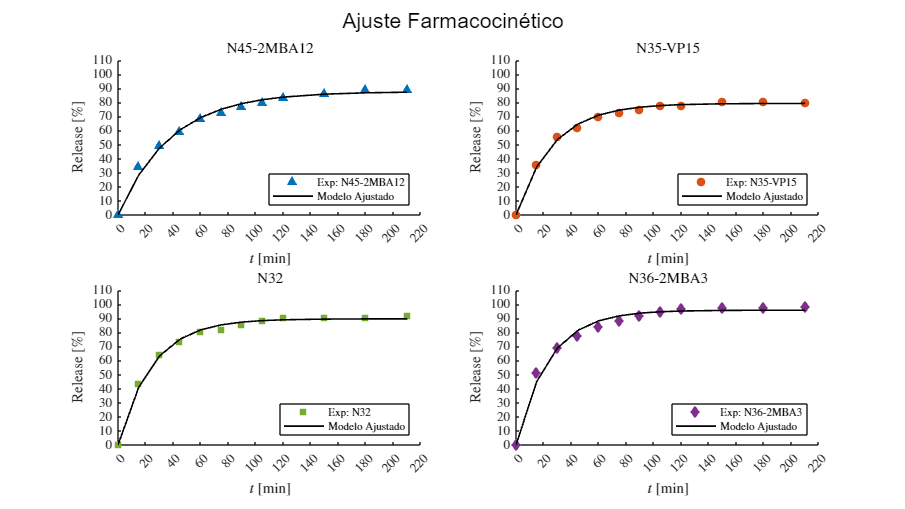

plotResults(t, V, xp_farmaco, 'Ajuste Farmacocinético', 'Farmaco_Result');

### Eureqa : Función del tiempo

xp_eureqa = zeros(size(V));
rhoi1 = 11.6; rhoi2 = 0.371;
for i = 1:4
    disp(['Ajustando Farmaco para: ', labels(i)])
    mdl = eureqa(t, V(:,i), [rhoi1; rhoi2]);
    xp_eureqa(:,i) = mdl.Fitted; 
end

    "Ajustando Farmaco para: "    "N45_2MBA12"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE             CI95             Pvalue  
    __________    ________    ________    ________    _________________    __________

    {'rhoi1'}      11.171      0.24373     0.54307    10.628     11.714     5.889e-13
    {'rhoi2'}     0.33679     0.021042    0.046885    0.2899    0.38367    1.8717e-08

R-cuadrada ordinaria: 0.99573
Suma residual de cuadrados: 33.561
Criterio de informacion de Akaike ajustado (n/k<40): 51.7294

    "Ajustando Farmaco para: "    "N35_VP15"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate      SE         MoE              CI95             Pvalue  
    __________    ________    _______    ________    __________________    __________

    {'rhoi1'}      12.456     0.27498      0.6127     11.844     13.069    6.6157e-13
    {'rhoi2'}     0.47884     0.02374    0.052896    0.42595    0.53174    1.9753e-09

R-cuadrada ordinaria: 0.99332
Suma residual de cuadrados: 42.7179
Criterio de informacion de Akaike ajustado (n/k<40): 54.6244

    "Ajustando Farmaco para: "    "N32"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

    {'rhoi1'}      14.502      0.26591     0.59249      13.91     15.095     1.041e-13
    {'rhoi2'}     0.57182     0.022957    0.051151    0.52067    0.62297    2.4878e-10

R-cuadrada ordinaria: 0.99503
Suma residual de cuadrados: 39.9462
Criterio de informacion de Akaike ajustado (n/k<40): 53.8194

    "Ajustando Farmaco para: "    "N36_2MBA3"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE             CI95             Pvalue  
    __________    ________    ________    _______    __________________    __________

    {'rhoi1'}      15.683      0.13339    0.29722     15.386      15.98    4.8602e-17
    {'rhoi2'}     0.62352     0.011516    0.02566    0.59786    0.64918    1.1191e-13

R-cuadrada ordinaria: 0.99888
Suma residual de cuadrados: 10.0523
Criterio de informacion de Akaike ajustado (n/k<40): 37.2626

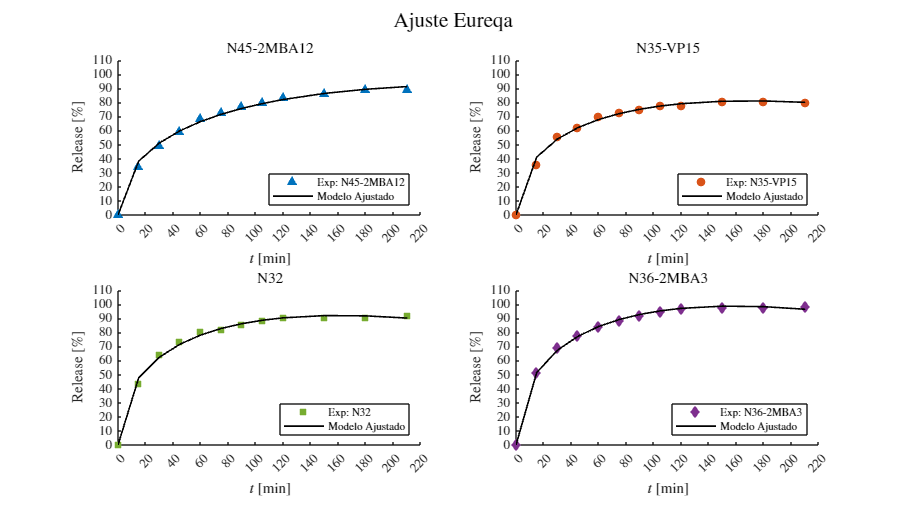

plotResults(t, V, xp_eureqa, 'Ajuste Eureqa', 'Eureqa_Result');

### Eureqa : Función diferencial

xp_eureqa = zeros(size(V));
rhoi1 = 2.27; rhoi2 = 0.0259;
for i = 1:4
    disp(['Ajustando Farmaco para: ', labels(i)])
    mdl = eureqadif(t, V(:,i), [rhoi1; rhoi2]);
    xp_eureqa(:,i) = mdl.Fitted; 
end

    "Ajustando Farmaco para: "    "N45_2MBA12"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE              CI95             Pvalue  
    __________    ________    _________    _________    __________________    __________

    {'rhoi1'}       2.2766      0.10482      0.23355     2.043      2.5101    9.5724e-10
    {'rhoi2'}     0.026009    0.0014852    0.0033092    0.0227    0.029318    7.8302e-09

R-cuadrada ordinaria: 0.99159
Suma residual de cuadrados: 66.0644
Criterio de informacion de Akaike ajustado (n/k<40): 59.8565

    "Ajustando Farmaco para: "    "N35_VP15"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

    {'rhoi1'}       2.9697      0.10136      0.22586      2.7438      3.1955    5.0099e-11
    {'rhoi2'}     0.037487    0.0014667    0.0032681    0.034219    0.040755      1.93e-10

R-cuadrada ordinaria: 0.99615
Suma residual de cuadrados: 24.6378
Criterio de informacion de Akaike ajustado (n/k<40): 48.0204

    "Ajustando Farmaco para: "    "N32"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    ________    _________    ____________________    __________

    {'rhoi1'}       3.6338     0.14119      0.31459      3.3192      3.9484     1.802e-10
    {'rhoi2'}     0.040578    0.001784    0.0039749    0.036603    0.044553    6.0804e-10

R-cuadrada ordinaria: 0.99519
Suma residual de cuadrados: 38.6673
Criterio de informacion de Akaike ajustado (n/k<40): 53.4289

    "Ajustando Farmaco para: "    "N36_2MBA3"



Cantidad de datos : 12
Cantidad de parametros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

    {'rhoi1'}       4.0436      0.24638      0.54897      3.4947      4.5926    1.4685e-08
    {'rhoi2'}     0.042257    0.0028953    0.0064512    0.035806    0.048709    4.5469e-08

R-cuadrada ordinaria: 0.98828
Suma residual de cuadrados: 105.3702
Criterio de informacion de Akaike ajustado (n/k<40): 65.4587

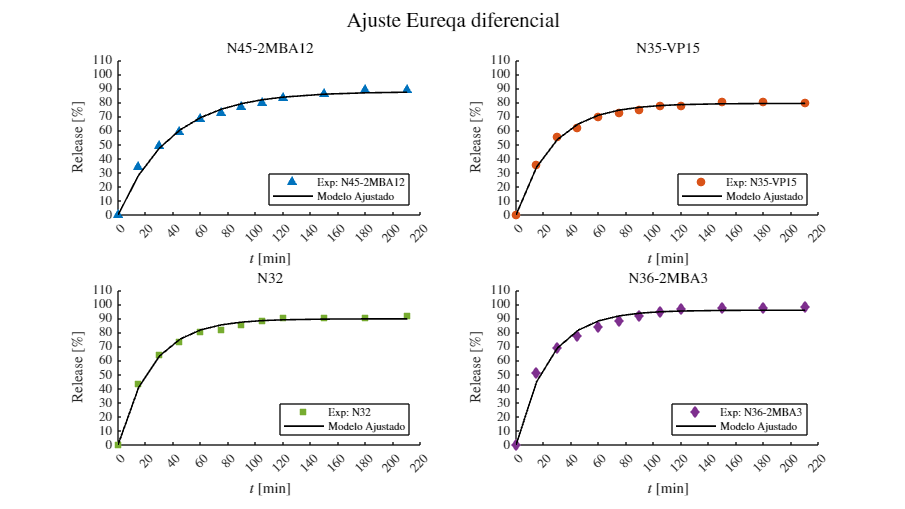

plotResults(t, V, xp_eureqa, 'Ajuste Eureqa diferencial', 'EureqaDif_Result');

## Funciones

function graficarPuntos(file, smooth, normalize)
    % Cargar datos
    try
        sys = readmatrix(file);
    catch
        error('No se pudo leer el archivo. Asegúrate de que el nombre y la extensión sean correctos.');
    end    
    to = sys(:, 1);
    v1 = sys(:, 2); v2 = sys(:, 3); v3 = sys(:, 4); v4 = sys(:, 5);
    if normalize
        to = to - to(1); 
        v1 = (v1 ./ max(v1)) * 100; 
        v2 = (v2 ./ max(v2)) * 100; 
        v3 = (v3 ./ max(v3)) * 100; 
        v4 = (v4 ./ max(v4)) * 100;
    end
    if smooth
        window = 5;
        v1 = smoothdata(v1, 'gaussian', window);
        v2 = smoothdata(v2, 'gaussian', window);
        v3 = smoothdata(v3, 'gaussian', window);
        v4 = smoothdata(v4, 'gaussian', window);
    end
    figure('Name', 'Visualización de Datos de Liberación', 'Color', 'w');
    hold on;
    plot(to, v2, 'o', 'LineWidth', 1, 'MarkerSize', 6, 'DisplayName', '$X_1(t): {N35-VP15}$');
    plot(to, v3, 's', 'LineWidth', 1, 'MarkerSize', 6, 'DisplayName', '$X_2(t): {N32}$');
    plot(to, v4, 'd', 'LineWidth', 1, 'MarkerSize', 6, 'DisplayName', '$X_3(t): {N36-2MBA3}$');
    plot(to, v1, '^', 'LineWidth', 1, 'MarkerSize', 6, 'DisplayName', '$X_4(t): {N45-2MBA12}$');
    xlim([0 220]);
    xticks(0:20:220);
    ylim([0 100]);
    yticks(0:10:100);
    if normalize; ylim([0 110]); end
    grid off;
    set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 12);
    xlabel('t [$min$]', 'Interpreter', 'latex', 'FontSize', 14);
    ylabel('Cumulative drug release ($\%$)', 'Interpreter', 'latex', 'FontSize', 14);
    legend('Location', 'best', 'Interpreter', 'latex');
    hold off;
    exportgraphics(gcf, 'Raw.pdf', 'ContentType', 'vector');
end

### Datos experimentales

function [t, V] = imprimirTabla(file)
    data = readmatrix(file);
    t = data(:, 1);
    V = data(:, 2:5); 
    T = table(t, V(:,1), V(:,2), V(:,3), V(:,4), ...
        'VariableNames', {'Tiempo_min', 'N45_2MBA12', 'N35_VP15', 'N32', 'N36_2MBA3'});

    % Mostrar la tabla
    fprintf('\n--- Datos cargados de: %s ---\n', file);
    disp(T);
end

### Modelos matemáticos y bioestadísticos

function mdl = peppas(to, xo, par)
    to = to(:); 
    xo = xo(:);
    function x = model(par, t)
        k = par(1); n = par(2);
        x = k * t.^n;
    end
    mdl = fitnlm(to, xo, @model, par);
    Parameters = {'k'; 'n'}; 
    biostats(mdl, Parameters,xo);
end

function mdl = farmaco(to,xo,par)
    to = to(:); 
    xo = xo(:);
    function x = model(par,t)
        k = par(1);
        beta = par(2);
        x =  beta.*(1-exp(-k.*t));
    end
    mdl = fitnlm(to, xo, @model, par);
    Parameters = {'k'; 'beta'};
    biostats(mdl, Parameters, xo);
end
function mdl = eureqa(to,xo,par)
    to = to(:); 
    xo = xo(:);
    function x = model(par,t)
        rhoi1 = par(1);
        rhoi2 = par(2);
        x =  rhoi1.*sqrt(t) - rhoi2.*t;
    end
    mdl = fitnlm(to, xo, @model, par);
    Parameters = {'rhoi1'; 'rhoi2'};
    biostats(mdl, Parameters, xo);
end
function mdl = eureqadif(to,xo,par)
    to = to(:); 
    xo = xo(:);
    function x = model(par,xo)
        rhoi1 = par(1);
        rhoi2 = par(2);
        xdx =  @(t, xo) rhoi1 - rhoi2 *xo;
        [~, x] = ode45(xdx, to, 0);
    end
    mdl = fitnlm(to, xo, @model, par);
    Parameters = {'rhoi1'; 'rhoi2'};
    biostats(mdl, Parameters, xo);
end

function biostats(mdl, Parameters,xo)
    Estimate = mdl.Coefficients.Estimate;
    SE = mdl.Coefficients.SE;
    Pvalue = mdl.Coefficients.pValue;  
    alpha = 0.05;
    CI95 = coefCI(mdl, alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2, dof);
    MoE = SE * tval;
    Results = table(Parameters, Estimate, SE, MoE, CI95, Pvalue); 
    disp(['Cantidad de datos : ', num2str(length(xo(:,1)))])
    disp(['Cantidad de parametros: ',num2str(length(Parameters))])
    disp(['Degrees of freedom: ', num2str(dof)])
    disp(['t-student value: ', num2str(tval)])
    disp(['Significance value (alpha): ', num2str(alpha)])
    disp(' '); disp(Results);
    R2o = mdl.Rsquared.Ordinary;
    SSE = mdl.SSE;
    AICc = mdl.ModelCriterion.AICc;
    fprintf(['R-cuadrada ordinaria: ', num2str(R2o)]);...
    fprintf(['\nSuma residual de cuadrados: ', num2str(SSE)]);...
    fprintf(['\nCriterio de informacion de Akaike ajustado (n/k<40): ', num2str(AICc)]);
end
function plotResults(t, V, V_fit, titulo, fileName)
    labels  = {'N45-2MBA12', 'N35-VP15', 'N32', 'N36-2MBA3'};
    colors  = {'#0072BD','#D95319','#77AC30','#7E2F8E'};
    markers = {'^','o','s','d'};

    figure('Name', titulo, 'Color', 'w', 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.8]);
    grid off;

    for i = 1:4
        subplot(2,2,i); hold on;
        
        % 1. Graficar puntos experimentales
        plot(t, V(:,i), markers{i}, 'Color', colors{i}, ...
             'MarkerFaceColor', colors{i}, 'MarkerSize', 6, ...
             'DisplayName', ['Exp: ', labels{i}]);
        
        % 2. Graficar la línea del modelo (usando los datos de xp que ya calculaste)
        plot(t, V_fit(:,i), '-k', 'LineWidth', 1.2, ...
             'DisplayName', 'Modelo Ajustado');

        % Formato profesional
        xlim([0 220]); xticks(0:20:220);
        ylim([0 110]); yticks(0:10:110);
        grid off; 
        set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 10);
        xlabel('$t$ [min]', 'Interpreter', 'latex');
        ylabel('Release [\%]', 'Interpreter', 'latex');
        legend('Location', 'southeast', 'Interpreter', 'latex', 'FontSize', 8);
        title(labels{i}, 'Interpreter', 'latex');
    end
    
    sgtitle(titulo, 'Interpreter', 'latex', 'FontSize', 16);
    
    % Exportar automáticamente
    exportgraphics(gcf, [fileName, '.pdf'], 'ContentType', 'vector');
end